# Decomposition Reaction of Dimethyl Ether 

The gas-phase 1st-order decomposition reaction of dimethyl ether


$${\mathrm{CH}}_3 {\mathrm{OCH}}_3 \to {\mathrm{CH}}_4 +\mathrm{CO}+H_2$$


 is carried out in a constant-volume batch reactor at 552°C. A mass balance on the batch reactor for  the 1st-order reaction gives:


$$\ln \left(\frac{3P_0 -P}{2P_0 }\right)=-\mathrm{kt}$$


where $P_0$ is the initial pressure ***P*** the measured pressure ***k*** is the rate constant. The following table shows pressure changes in the decomposition reaction. Determine the 1st-order rate  constant from the given data:

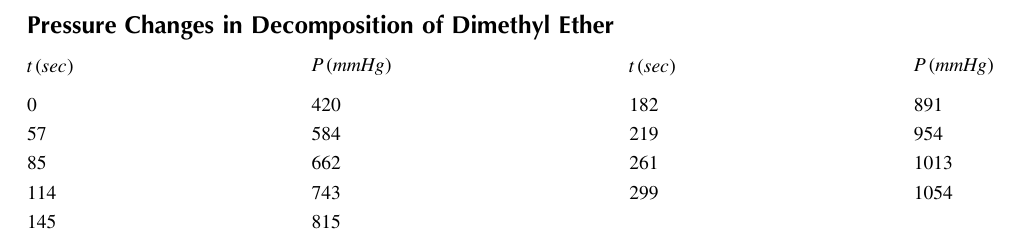

First of all, we have to calculate rate of reaction according to kinetics.

t = [0 57 85 114 145 182 219 261 299];
P = [420 584 662 743 815 891 954 1013 1054];
P0 = P(1);
rate = ones(1,length(P));
for i=2:length(rate)
    rate(i) = log((3*P0-P(i))/(2*P0));
end

Then, we have to divide rate to time, and it leads to find ***k ***

k = -rate./t;
disp(mean(k(2:end)))

    0.0044



**Extra: Plotting rate versus t**

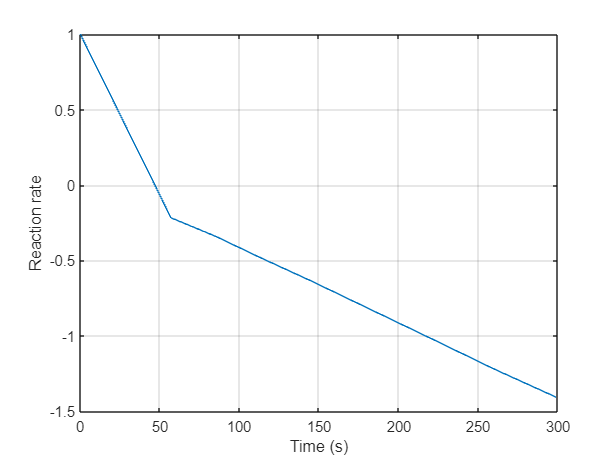

figure(1)
plot(t,rate)
xlabel('Time (s)')
ylabel('Reaction rate')
grid on

The change in curve slope at t=57 shows that there's another kinetic dominant in our system!